## Part (b)

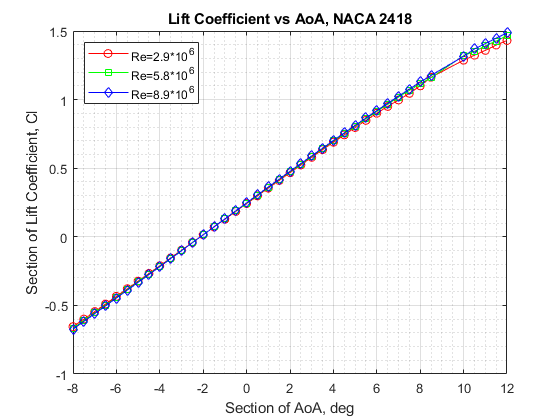

% Reading the csv files 
Re29 = csvread("T1_Re2.900_M0.00_N9.0.csv",10,0);
Re58 = csvread("T1_Re5.800_M0.00_N9.0.csv",10,0);
Re89 = csvread("T1_Re8.900_M0.00_N9.0.csv",10,0);

% Manipulating matrices to get vectors 
alpha = Re29(:,1);
Cl29 = Re29(:,2);
Cl58 = Re58(:,2);
Cl89 = Re89(:,2);

% Plotting 
fig1 = figure(1);
plot(alpha, Cl29, '-or')
title('Lift Coefficient vs AoA, NACA 2418')
xlabel('Section AoA, deg')
ylabel('Section Lift Coefficient, Cl')
grid on 
grid minor
box on
hold on
plot(alpha, Cl58, '-sg')
plot(alpha, Cl89, '-db')
hold off 
legend('Re=2.9*10^6', 'Re=5.8*10^6', 'Re=8.9*10^6','Location',"northwest")

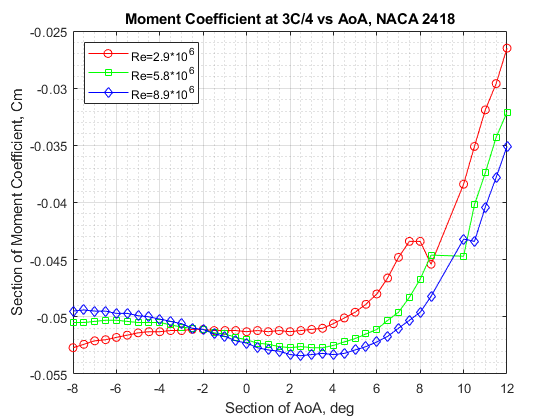


% Retriving moment coefficient values 
Cm29 = Re29(:,5);
Cm58 = Re58(:,5);
Cm89 = Re89(:,5);

% Plotting
fig2 = figure(2);
plot(alpha, Cm29, '-or')
title('Moment Coefficient at 3C/4 vs AoA, NACA 2418')
xlabel('Section of AoA, deg')
ylabel('Section of Moment Coefficient, Cm')
grid on 
grid minor
box on
hold on
plot(alpha, Cm58, '-sg')
plot(alpha, Cm89, '-db')
hold off 
legend('Re=2.9*10^6', 'Re=5.8*10^6', 'Re=8.9*10^6','Location',"northwest")

## Part (c)

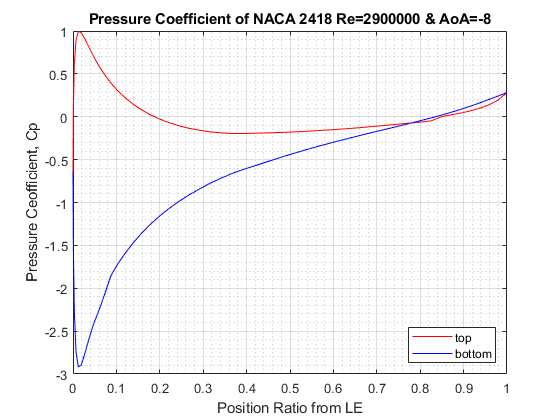

% Import csv file for pressure coefficient 
Cp = csvread("cp.csv", 6, 0);

% X-values and y_values 
X = Cp(:,1);
X_top = X(1:50,1);
X_bot = X(50:99,1);
Cpv = Cp(:,3);
Cpv_top = Cpv(1:50,1);
Cpv_bot = Cpv(50:99, 1);

% Plotting pressure coefficient 
fig3 = figure(3);
plot(X_top, Cpv_top,'-r')
title('Pressure Coefficient of NACA 2418 Re=2900000 & AoA=-8')
xlabel('Position Ratio from LE')
ylabel('Pressure Ceofficient, Cp')
grid on 
grid minor
box on
hold on
plot(X_bot, Cpv_bot,'-b' )
hold off
legend('top', 'bottom', 'Location',"southeast")

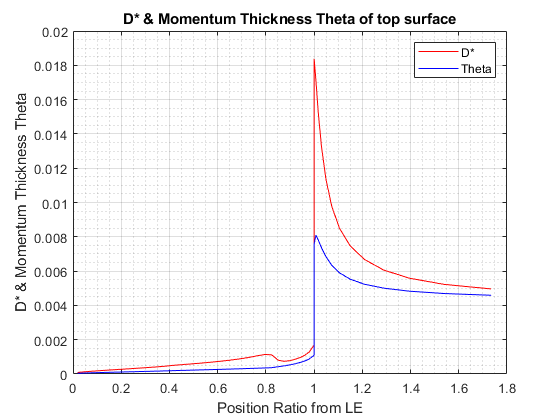


% Import csv file for D* 
D_mmt_top = csvread("topD_theta.csv", 1, 3);

% Getting x-values and y-values 
X1 = D_mmt_top(:,1);
D1 = D_mmt_top(:,2);
theta1 = D_mmt_top(:,5);

% Plotting 
fig4 = figure(4);
plot(X1, D1, '-r');
title('D* & Momentum Thickness Theta of top surface')
xlabel('Position Ratio from LE')
ylabel('D* & Momentum Thickness Theta')
grid on 
grid minor
box on
hold on
plot(X1, theta1, '-b')
hold off
legend('D*', 'Theta')

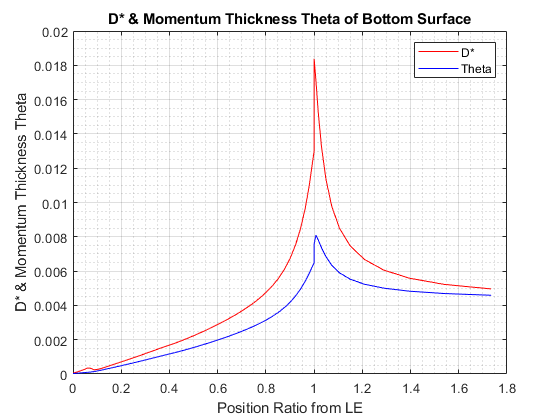


% Import csv file for D* 
D_mmt_bot = csvread("botD_theta.csv", 1, 3);

% Getting x-values and y-values 
X2 = D_mmt_bot(:,1);
D2 = D_mmt_bot(:,2);
theta2 = D_mmt_bot(:,5);

% Plotting 
fig5 = figure(5);
plot(X2, D2, '-r');
title('D* & Momentum Thickness Theta of Bottom Surface')
xlabel('Position Ratio from LE')
ylabel('D* & Momentum Thickness Theta')
grid on 
grid minor
box on
hold on
plot(X2, theta2, '-b')
hold off
legend('D*', 'Theta')

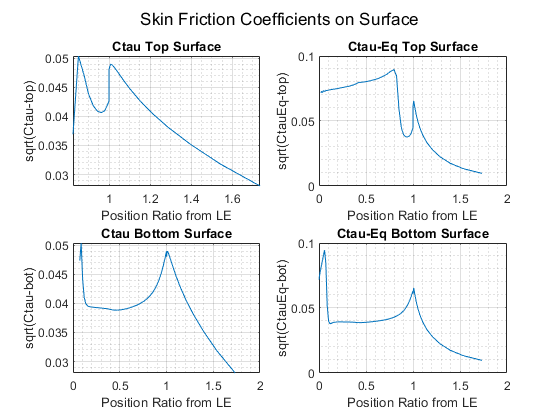


% Import csv file
skinfric = csvread("skinFricCoeff.csv", 1,3);

% Assigning variables
a1 = skinfric(1:23,1);
a2 = skinfric(1:58,4);
a3 = skinfric(1:53,7);
a4 = skinfric(5:67, 10);
tau_top = skinfric(1:23,2);
tauEq_top = skinfric(1:58,5);
tau_bot = skinfric(1:53,8);
tauEq_bot = skinfric(5:67, 11);

%Plotting
fig6 = figure(6);
subplot(2,2,1)
plot(a1, tau_top, '-');
title('Ctau Top Surface')
xlabel('Position Ratio from LE')
ylabel('sqrt(Ctau-top)')
grid on 
grid minor
box on

subplot(2,2,2)
plot(a2, tauEq_top, '-');
title('Ctau-Eq Top Surface')
xlabel('Position Ratio from LE')
ylabel('sqrt(CtauEq-top)')
grid on 
grid minor
box on

subplot(2,2,3)
plot(a3, tau_bot, '-');
title('Ctau Bottom Surface')
xlabel('Position Ratio from LE')
ylabel('sqrt(Ctau-bot)')
grid on 
grid minor
box on

subplot(2,2,4)
plot(a4, tauEq_bot, '-');
title('Ctau-Eq Bottom Surface')
xlabel('Position Ratio from LE')
ylabel('sqrt(CtauEq-bot)')
grid on 
grid minor
box on

sgtitle("Skin Friction Coefficients on Surface")

## Part (d)

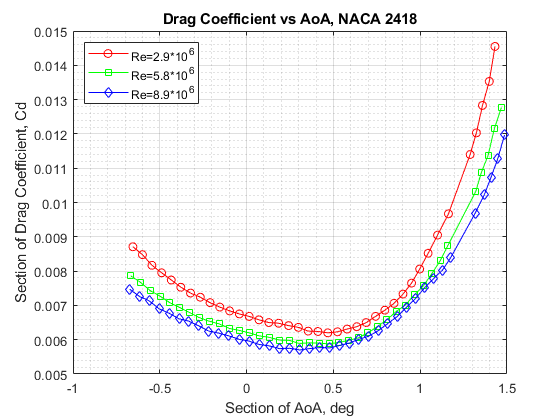

% Assigning necessary variables
Cd29 = Re29(:,3);
Cd58 = Re58(:,3);
Cd89 = Re89(:,3);

% Plotting 
fig7 = figure(7);
plot(Cl29, Cd29, '-or')
title('Drag Coefficient vs AoA, NACA 2418')
xlabel('Section Lift Coefficients, deg')
ylabel('Section Drag Coefficient, Cd')
grid on 
grid minor
box on
hold on
plot(Cl58, Cd58, '-sg')
plot(Cl89, Cd89, '-db')
hold off 
legend('Re=2.9*10^6', 'Re=5.8*10^6', 'Re=8.9*10^6','Location',"northwest")